# ESAME___17/07/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili Simboliche 

syms x1 x2 x3 x4 dx1 dx2 dx3 dx4 u1 u2 real

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [x1;
     x2;
     x3;
     x4];

% Uscita
y = [x1;
     x3];

% Dimensioni
n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Punto di Equilibrio 

x_bar = [0;
         0;
         0;
         0];

u_bar = [0;
         -0.1];

#### Modello Dinamico Non LIneare

eq1_sym = dx1 == x2;
eq2_sym = dx2 == -0.8*sin(x1) - 0.5*x2 + 0.3*x4 +u1;
eq3_sym = dx3 == x4;
eq4_sym = dx4 == -0.6*sin(x3) - 0.4*x4 + 0.2*x2 + u2 + 0.1*cos(x1);

eqs_sym = [eq1_sym;
           eq2_sym;
           eq3_sym;
           eq4_sym];

% dx/dt
f = [dx1;
     dx2;
     dx3;
     dx4];

% y
g = y;

## 1)  LINEARIZZAZIONE

#### Verifica Punto di Equilibrio

f1 = x2;
f2 = -0.8*sin(x1) - 0.5*x2 + 0.3*x4 + u1;
f3 = x4;
f4 = -0.6*sin(x3) - 0.4*x4 + 0.2*x2 + u2 + 0.1*cos(x1);

f_expr = [f1; f2; f3; f4];


f_eq_val = subs(f_expr, [x1; x2; x3; x4; u1; u2], [x_bar; u_bar]);


check = double(f_eq_val);


tol = 1e-10;
if all(abs(check) < tol)
    fprintf('CONFERMATO: Il punto è di equilibrio (derivata nulla).\n');
else
    fprintf('ERRORE: Il punto NON è di equilibrio.\n');
    disp('Valori delle derivate in x_bar, u_bar:');
    disp(check);
end

CONFERMATO: Il punto è di equilibrio (derivata nulla).


#### Linearizzazione intorno a (x_bar, u_bar)

f_sym = solve(eqs_sym, [dx1, dx2, dx3, dx4], "ReturnConditions",true);

f = [f_sym.dx1;
     f_sym.dx2;
     f_sym.dx3;
     f_sym.dx4];

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);


A = double(subs(A_sym, [x;u], [x_bar; u_bar]));
B = double(subs(B_sym, [x;u], [x_bar; u_bar]));
C = double(subs(C_sym, [x;u], [x_bar; u_bar]));
D = double(subs(D_sym, [x;u], [x_bar; u_bar]));

sys = ss(A, B, C, D)


sys =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2  -0.8  -0.5     0   0.3
   x3     0     0     0     1
   x4     0   0.2  -0.6  -0.4
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Controllabilità e Osservabilità del sistema Linearizzato

Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## 2)  ASSEGNAMENTO AUTOVALORI CON METODO DI SYLVESTER

#### Specifiche

% Autovalori desiderati
eig_des = [-2, -2.5, -3, -4];

% Condizione iniziale
x0_sylv = [0.1;
           0;
           -0.1;
           0];

#### Sintesi

Lambda = diag(eig_des);
G = rand(m,n);

X = sylvester(A, -Lambda, -B*G);
K_eig = -G/X

K_eig =    10.3301    6.3971   -6.2048   -2.1800
    0.2312    0.3457    4.6619    4.2029



A_cl_eig = A - B*K_eig;

disp(eig(A)); disp(eig(A_cl_eig));

  -0.3348 + 0.7674i
  -0.3348 - 0.7674i
  -0.1152 + 0.8194i
  -0.1152 - 0.8194i

   -4.0000
   -3.0000
   -2.5000
   -2.0000



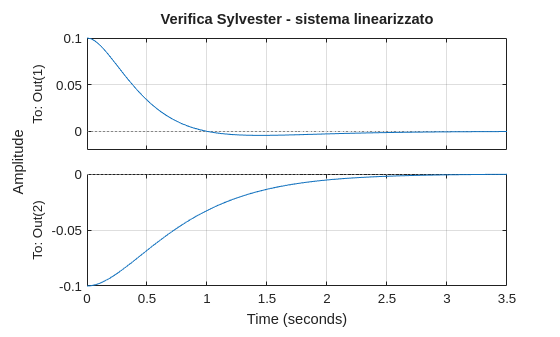

sys_eig = ss(A_cl_eig, B, C, D);

figure;
initial(sys_eig, x0_sylv);
grid on
title('Verifica Sylvester - sistema linearizzato');

#### Verifica Sistema Non Lineare

tspan = [0 20]; % Secondi di simulazione

f_non_linear = @(t, x) dinamica_nonlineare(t, x, K_eig, u_bar);

f_non_linear = function_handle with value:
    @(t,x)dinamica_nonlineare(t,x,K_eig,u_bar)


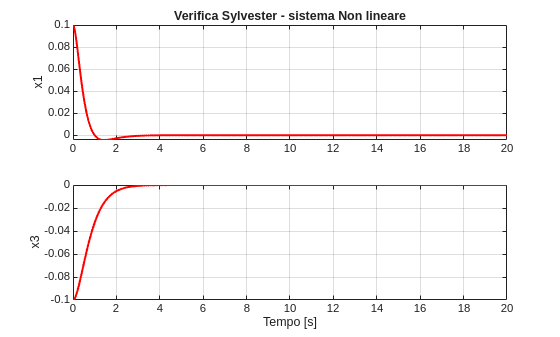

[t_sim, x_sim] = ode45(f_non_linear, tspan, x0_sylv);

figure;
subplot(2,1,1);
plot(t_sim, x_sim(:,1), 'r', 'LineWidth', 1.5);
grid on; ylabel('x1'); title('Verifica Sylvester - sistema Non lineare');

subplot(2,1,2);
plot(t_sim, x_sim(:,3), 'r', 'LineWidth', 1.5);
grid on; ylabel('x3'); xlabel('Tempo [s]');

## 3)  REGOLATORE LQR CON AZIONE INTEGRATIVA

#### Specifiche

% numero di variabili da aggiungere allo stato (errori)
z = 2;

% dimensione dello stato aumentato
n_aug = n+z;

% Tempo di assestamento desiderato

Ts = 0.9;
alpha = 4/Ts;

% Sovraelongazione massima percentuale
max_ov_perc = 10;

% Riferimento costante 
r = [0.2;
     -0.1];

#### Sistema aumentato

A_aug = [A, zeros(n,z);
         -C, zeros(z,z)];

% Shift su A_aug per rispettare il Ts<1s
A_hat = A_aug + alpha*eye(n_aug);

B_aug = [B;
         zeros(z,m)];

C_aug = [eye(n), zeros(n,z)];

D_aug = zeros(n,m);

sys_aug = ss(A_hat, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1  4.444      1      0      0      0      0
   x2   -0.8  3.944      0    0.3      0      0
   x3      0      0  4.444      1      0      0
   x4      0    0.2   -0.6  4.044      0      0
   x5     -1      0      0      0  4.444      0
   x6      0      0     -1      0      0  4.444
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
   x5   0   0
   x6   0   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


#### Sintesi LQR

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 20*eye(z))

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0    20     0
     0     0     0     0     0    20


R = eye(m)

R =      1     0
     0     1


K_LQR = lqr(sys_aug, Q, R)

K_LQR =   230.3314   25.7888    3.4094    0.4914 -679.7215  -15.1832
    5.1759    0.4914  232.2757   25.9981  -22.9847 -686.5930


K_LQR_x = K_LQR(:, 1:n);

K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

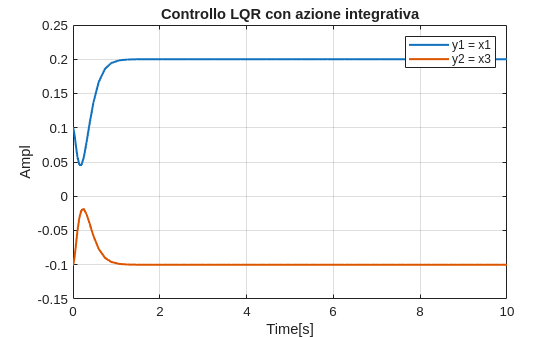

% Plot MATLAB
out = sim('LQR_DE6000008.slx');
y_lqr = out.y.Data;
y_impianto_lqr = out.y_impianto_lqr.Data;
y_impianto_lqr_time = out.y_impianto_lqr.Time;
u_lqr = out.u_lqr.Data;
u_lqr_time = out.u_lqr.Time;
time = out.y.Time;

figure
plot(time, y_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x3');
title('Controllo LQR con azione integrativa');

## 4)  CONTROLLO LQG

#### Specifiche 

W = 0.01*eye(n);
V = 0.001*eye(m);

Qv = W;
Rv = V;

#### Sistema Perturbato

G = eye(n);

sys_perturbato = ss(A, [B G], C, zeros(size(C,1), size([B G],2)))


sys_perturbato =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2  -0.8  -0.5     0   0.3
   x3     0     0     0     1
   x4     0   0.2  -0.6  -0.4
 
  B = 
       u1  u2  u3  u4  u5  u6
   x1   0   0   1   0   0   0
   x2   1   0   0   1   0   0
   x3   0   0   0   0   1   0
   x4   0   1   0   0   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2  u3  u4  u5  u6
   y1   0   0   0   0   0   0
   y2   0   0   0   0   0   0
 
Continuous-time state-space model.


#### Kalman Filter

% Guadagno di Kalman
[~, L, ~] = kalman(sys_perturbato, Qv, Rv);

A_kf = A - L*C(1:2,:);
B_kf = [B L];
C_kf = eye(n);
D_kf = zeros(size(C_kf,1), size(B_kf,2));

KF = ss(A_kf, B_kf, C_kf, D_kf)


KF =
 
  A = 
            x1       x2       x3       x4
   x1   -3.519        1  -0.1454        0
   x2   -2.001     -0.5   -0.534      0.3
   x3  -0.1454        0   -3.603        1
   x4  -0.5018      0.2   -2.101     -0.4
 
  B = 
           u1      u2      u3      u4
   x1       0       0   3.519  0.1454
   x2       1       0   1.201   0.534
   x3       0       0  0.1454   3.603
   x4       0       1  0.5018   1.501
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3  u4
   y1   0   0   0   0
   y2   0   0   0   0
   y3   0   0   0   0
   y4   0   0   0   0
 
Continuous-time state-space model.


#### Verifica Simulazione

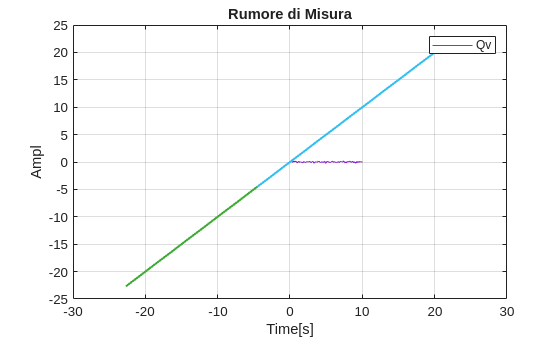

% Plot MATLAB
out = sim('LQG_DE6000008.slx');
y_lqg = out.y.Data;
Rv_sim = out.R.Data;
Qv_sim = out.Q.Data;
time = out.y.Time;
noise_time = out.Q.Time;

figure
plot(noise_time, Qv_sim, "LineWidth", 0.5);
grid on
hold on
plot(u_lqr, u_lqr, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('Qv');
title('Rumore di Misura');

hold off

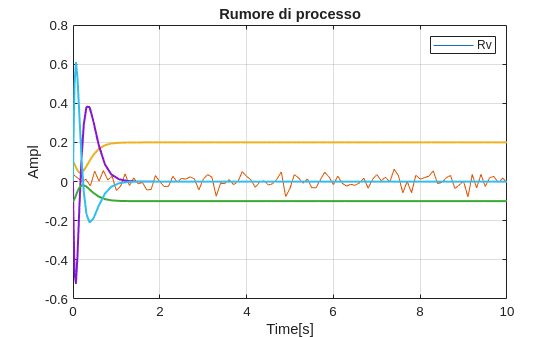

plot(noise_time, Rv_sim, "LineWidth", 0.5);
grid on
hold on
plot(y_impianto_lqr_time, y_impianto_lqr, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('Rv');
title('Rumore di processo');

hold off

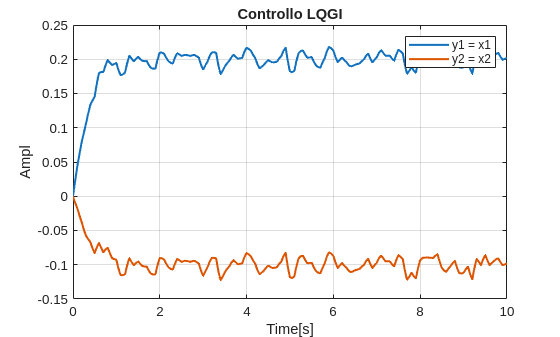

plot(time, y_lqg, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x2');
title('Controllo LQGI');

## 5)  Compressione mediante SVD

#### Lettura dell'immagine e conversione in scala di grigi

I_orig = imread('Image 17 lug 2026, 14_27_43.png');
I_gray = rgb2gray(I_orig);
I = double(I_gray);

#### Immagine Originale in scala di grigi

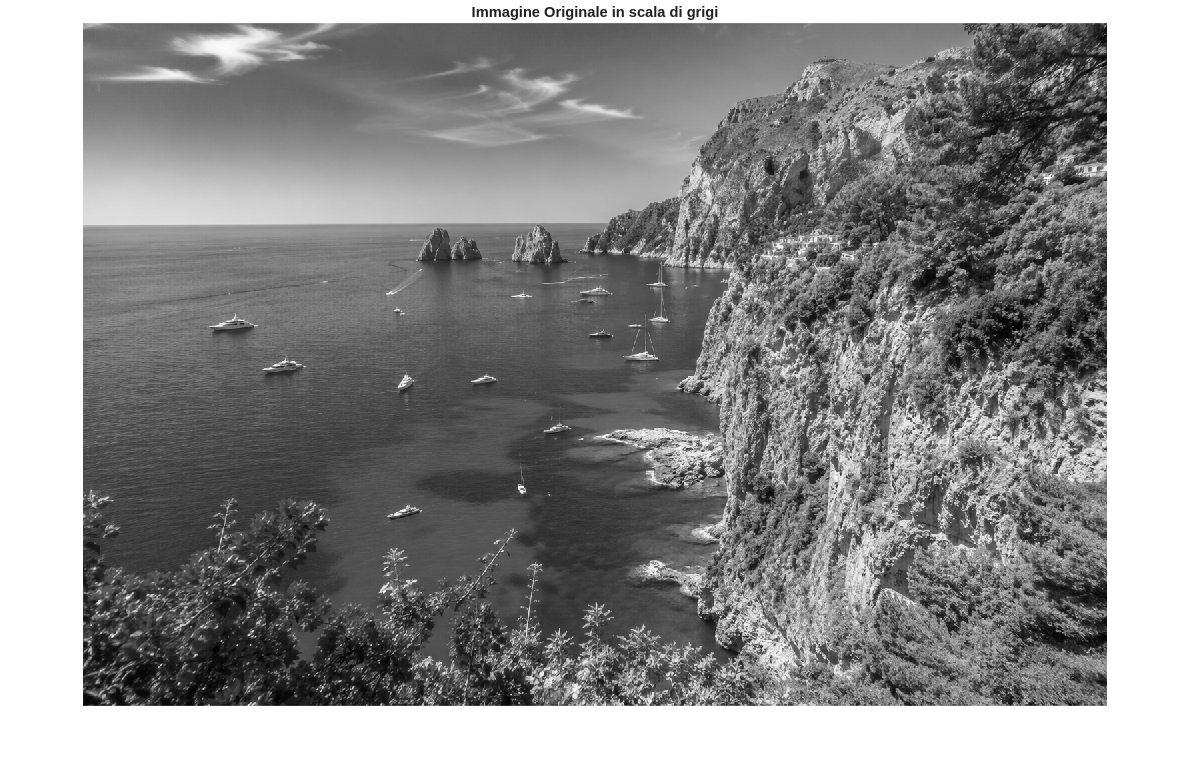

figure;
imshow(uint8(I_gray));
title('Immagine Originale in scala di grigi');

#### Decomposizione SVD

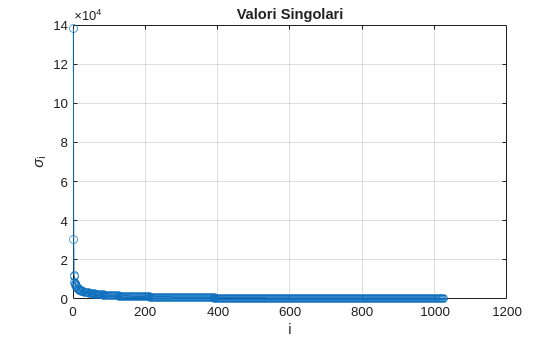

[U, S, V] = svd(I, 'econ');
singvals = diag(S);

figure;
plot(singvals, 'o-');
title('Valori Singolari');
xlabel('i');
ylabel('\sigma_i');
grid on;

#### Compressione 

sigma_max = singvals(1);
soglia = 0.01*sigma_max;

% Cerchiamo l'indice dell'ultimo valore singolare che rispetta la
% condizione sigma_i >= 0.01*sigma_max
r = find(singvals >= soglia, 1, 'last')

r = 146

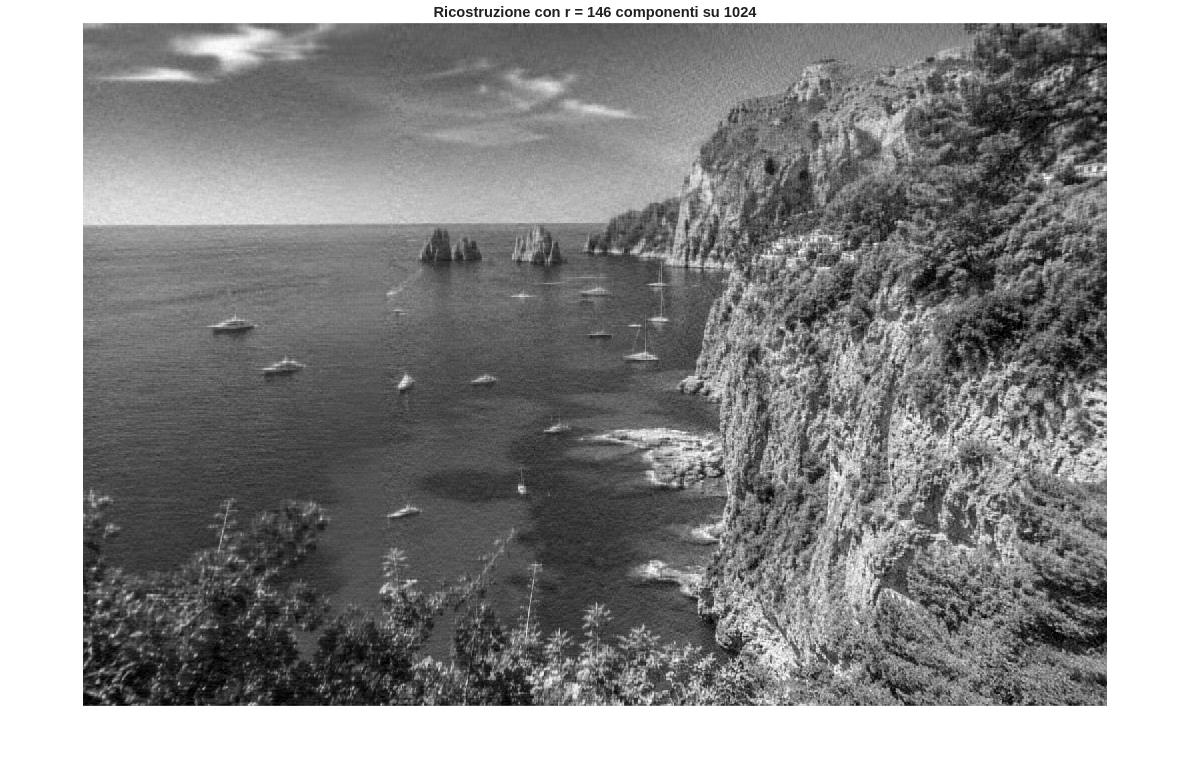

% Ricostruiamo l'immagine usando solo le prime r componenti
U_r = U(:,1:r);
S_r = S(1:r,1:r);
V_r = V(:,1:r);

% Ricostruzione Immagine Compressa
I_compressa = U_r*S_r*V_r';

figure;
imshow(uint8(I_compressa));
title(sprintf('Ricostruzione con r = %d componenti su %d', r, length(singvals)));

### Rapporto di Compressione e Errore di Ricostruzione

#### Rapporto di Compressione 

m_i = size(I,1);
n_i = size(I,2);

num_originale = m_i * n_i *3;
num_compressa = r*(m_i+n_i+1)*3;
tasso_compr = 100*(1-num_compressa/num_originale);
fprintf('Rapporto di Compressione = %.4f%%\n', tasso_compr);

Rapporto di Compressione = 76.2277%


#### Errore di Ricostruzione 

err = norm(I - I_compressa, 'fro') / norm(I, 'fro');
fprintf('Errore relativo (Frobenius) = %.4f\n', err);

Errore relativo (Frobenius) = 0.1020
